# EJERCICIO 2

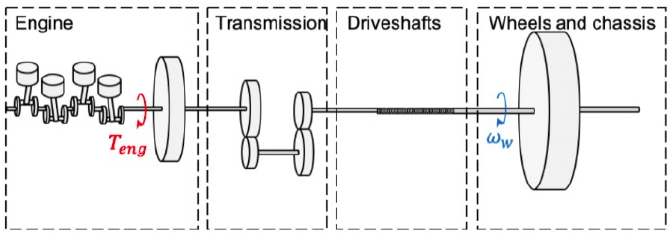

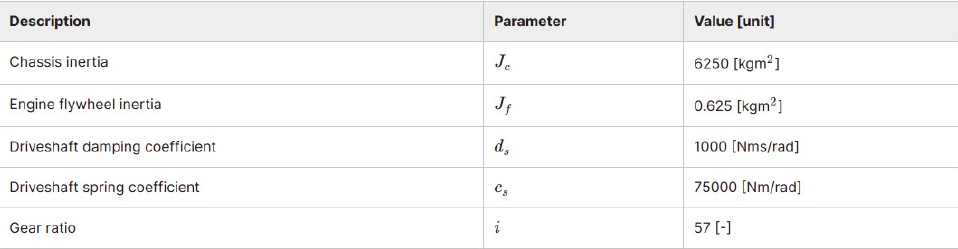

clc; clear; close all;
Jc = 6250;
Jf = 0.625;
ds = 1000;
cs = 75000;
GR = 57;   % gear ratio
M  = 2000; % masa de vehículo
G  = 9.82; % aceleración de la gravedad
R  = 0.34; % radio de la rueda
phi = 10;   % angulo de inclinación de la carretetera

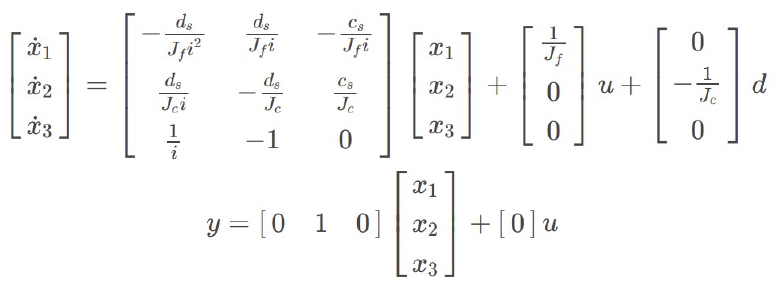

A  = [-ds/(Jf*GR^2) ds/(Jf*GR) -cs/(Jf*GR)
       ds/(Jc*GR)  -ds/(Jc)    cs/Jc
        1/GR           -1         0         ];
Bu = [1/Jf 0  0]';
Bd = [0 -1/Jc 0]';
Cp = [0   1   0];

## **1. Definición de los polos.**

Ubicar dos polos con:

wn   = 6;
zeta = 1/sqrt(2);
p1   = -wn*zeta + i*wn*sqrt(1-zeta^2);
p2   = p1';

El tercer polo se debe ubicar en:

p3   = -2*zeta*wn;

## 2. Encuentre el valor de la matriz K de realimentación por el método de Ackermann

K = acker(A, Bu, [p1 p2 p3])

K = 	1.0e+03 *

    0.0102    0.3255    1.9591


## 3. Encuentre el valor de kr.

kr = 1/(Cp*(-(A-Bu*K)\Bu))

kr = 906.8644

## 4. Encuentre los autovalores del sistema a lazo cerrado.

eig(A-Bu*K)

ans =   -8.4853 + 0.0000i
  -4.2426 + 4.2426i
  -4.2426 - 4.2426i


p1

p1 = -4.2426 + 4.2426i

p2

p2 = -4.2426 - 4.2426i

p3

p3 = -8.4853

# EJERCICIO 3

B  = [Bu Bd];                  % Put the B and H matrix together as one matrix B1 (for Simulink implementation purposes) 
C  = eye(3);                   % Output all state variables from the model
D  = zeros(3, 2);              % Corresponding D matrix
x0 = [120 2 0]';               % Initial conditions for the state variables

### Simulación

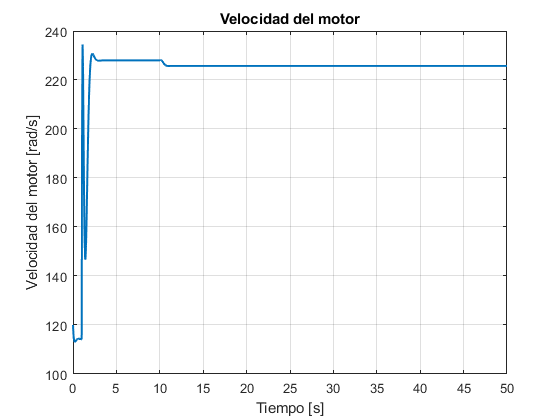

sim('Driveline_ctrl_sim');

tEngineSpeedMonitor   = EngineSpeedMonitor.time;
EngineSpeed           = EngineSpeedMonitor.signals.values;

tWheelSpeedMonitor    = WheelSpeedMonitor.time;
WheelSpeed            = WheelSpeedMonitor.signals.values;

tTorqueMonitor        = TorqueMonitor.time;
Torque                = TorqueMonitor.signals.values;

tControlSignalMonitor = ControlSignalMonitor.time;
ControlSignal         = ControlSignalMonitor.signals.values;

figure;
plot(tEngineSpeedMonitor, EngineSpeed, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad del motor [rad/s]');
title('Velocidad del motor');
grid on;

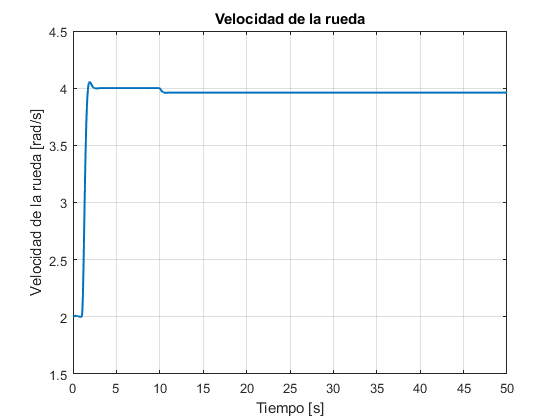

figure;
plot(tWheelSpeedMonitor, WheelSpeed, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad de la rueda [rad/s]');
title('Velocidad de la rueda');
grid on;

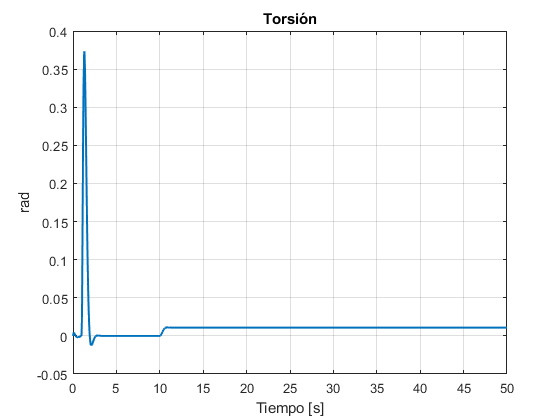

figure;
plot(tTorqueMonitor, Torque, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('rad');
title('Torsión');
grid on;

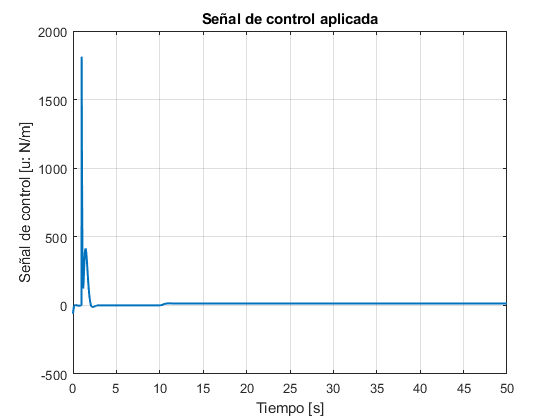

figure;
plot(tControlSignalMonitor, ControlSignal, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Señal de control [u: N/m]');
title('Señal de control aplicada');
grid on;

# LQR en vez de Acker

vtyp   = 60;       % km/h
vtyp   = vtyp/3.6; % m/s
vtyp   = vtyp/R;   % rad/s
Cpaux  = [Cp; A(2,:)];
acctyp = 9.81;                          % m/s^2
acctyp = acctyp*R;                      % rad/s^2

y2typ = acctyp*5.19; % Aceleración angular tpipica.
ytyp  = vtyp*  0.2; % Velocidad angular típica.
utyp  = 400*   6.04; % Nm engine torque typical.


Qy     = [1/(ytyp^2) 0
            0        1/(y2typ^2)];
Qx     = Cpaux'*Qy*Cpaux

Qx =     0.0000   -0.0000    0.0001
   -0.0000    0.0105   -0.0064
    0.0001   -0.0064    0.4805


Qu     = 1/(utyp^2);

[K, S] = lqr(A, Bu, Qx, Qu);
kr     = 1/(Cp*(-(A-Bu*K)\Bu));
K

K =     4.2643    3.3672  941.3619


kr

kr = 246.4320

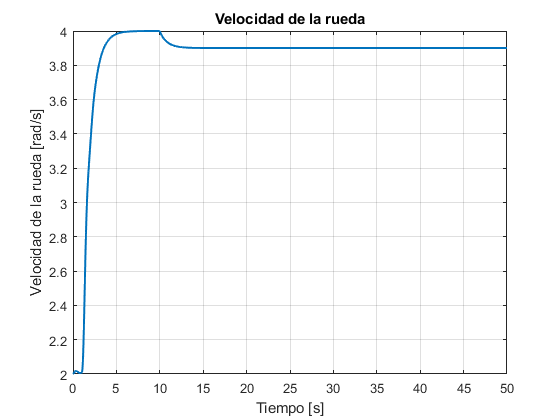

sim('Driveline_ctrl_sim');

tEngineSpeedMonitor   = EngineSpeedMonitor.time;
EngineSpeed           = EngineSpeedMonitor.signals.values;

tWheelSpeedMonitor    = WheelSpeedMonitor.time;
WheelSpeed            = WheelSpeedMonitor.signals.values;

tTorqueMonitor        = TorqueMonitor.time;
Torque                = TorqueMonitor.signals.values;

tControlSignalMonitor = ControlSignalMonitor.time;
ControlSignal         = ControlSignalMonitor.signals.values;

figure;
plot(tWheelSpeedMonitor, WheelSpeed, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad de la rueda [rad/s]');
title('Velocidad de la rueda');
grid on;

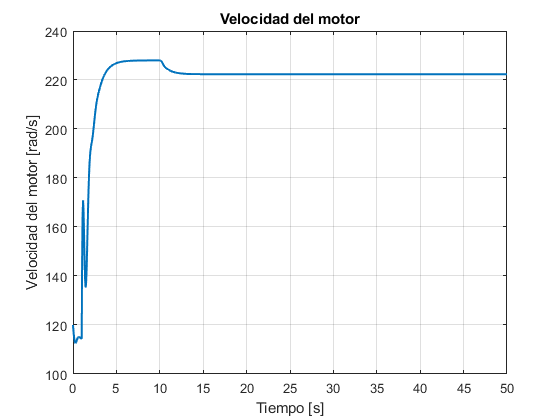


figure;
plot(tEngineSpeedMonitor, EngineSpeed, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad del motor [rad/s]');
title('Velocidad del motor');
grid on;

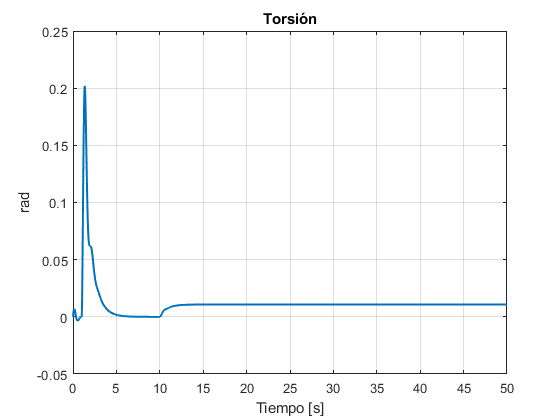


figure;
plot(tTorqueMonitor, Torque, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('rad');
title('Torsión');
grid on;

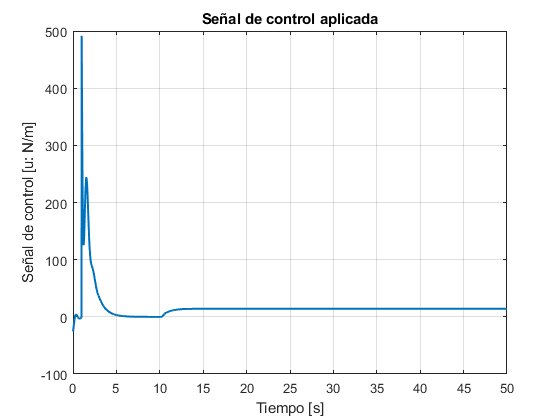


figure;
plot(tControlSignalMonitor, ControlSignal, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Señal de control [u: N/m]');
title('Señal de control aplicada');
grid on;

# LQR y ACCIÓN INTEGRAL

Aaug     = [A  zeros(3, 1)
            Cp     0      ]

Aaug = 	1.0e+03 *

   -0.0005    0.0281   -2.1053         0
    0.0000   -0.0002    0.0120         0
    0.0000   -0.0010         0         0
         0    0.0010         0         0


Baug     = [Bu; 0]

Baug =     1.6000
         0
         0
         0


ytyp   = vtyp*  0.4; % Velocidad angular típica.
y2typ  = acctyp*0.2; % Aceleración angular tpipica.
errtyp = 0.1;         % Integral del error típica
utyp   = 400*   0.2;  % Nm engine torque typical.

Qyaug   = [1/(ytyp^2)      0          0
            0        1/(y2typ^2)      0
            0             0       1/(errtyp^2)];
Cpauxaug = [Cpaux zeros(2, 1)
            0     0    0    1];
Qxaug    = Cpauxaug'*Qyaug*Cpauxaug

Qxaug =     0.0000   -0.0010    0.0757         0
   -0.0010    0.0601   -4.3146         0
    0.0757   -4.3146  323.5986         0
         0         0         0  100.0000


Qu     = 1/(utyp^2)

Qu = 1.5625e-04

rank([Baug, Aaug*Baug, Aaug^2*Baug, Aaug^3*Baug]) % es estabilizable el par

ans = 4

eig(Qxaug) % Qx semidefinida positiva, Qu es definida positiva

ans =   323.6562
    0.0000
    0.0026
  100.0000


eig([Qxaug zeros(4, 1); zeros(1, 4) Qu]) % caso aumentado

ans =   323.6562
    0.0000
    0.0026
  100.0000
    0.0002


eig([Qx zeros(3, 1); zeros(1, 3) Qu])   % caso sin aumentar

ans =          0
    0.4806
    0.0104
    0.0002


La única diferencia entre esos es que hay dos polos en el origen y uno solo en el otro.

[Kaug, S] = lqr(Aaug, Baug, Qxaug, Qu); % por alguna razón no se puede
K         = Kaug(1:end-1)

K = 	1.0e+03 *

    0.0049    0.3444    1.1549


ki = Kaug(end)

ki = 800.0000

kr     = 1/(Cp*(-(A-Bu*K)\Bu))

kr = 621.6424

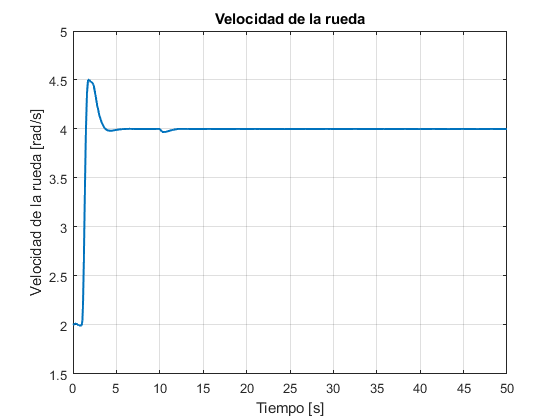

% Entonces lo que hacemos es conservar el diseño anterior sin acción
% integral y se la pongo ad hoc a prueba.

out = sim('Driveline_ctrl_sim_Int');

tEngineSpeedMonitor   = out.EngineSpeedMonitor.time;
EngineSpeed           = out.EngineSpeedMonitor.signals.values;

tWheelSpeedMonitor    = out.WheelSpeedMonitor.time;
WheelSpeed            = out.WheelSpeedMonitor.signals.values;

tTorqueMonitor        = out.TorqueMonitor.time;
Torque                = out.TorqueMonitor.signals.values;

tControlSignalMonitor = out.ControlSignalMonitor.time;
ControlSignal         = out.ControlSignalMonitor.signals.values;

figure;
plot(tWheelSpeedMonitor, WheelSpeed, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad de la rueda [rad/s]');
title('Velocidad de la rueda');
grid on;

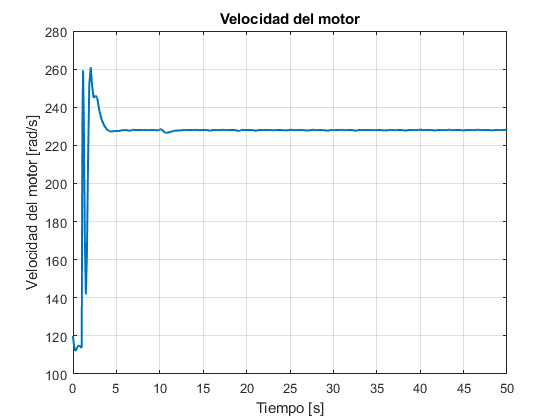

figure;
plot(tEngineSpeedMonitor, EngineSpeed, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Velocidad del motor [rad/s]');
title('Velocidad del motor');
grid on;

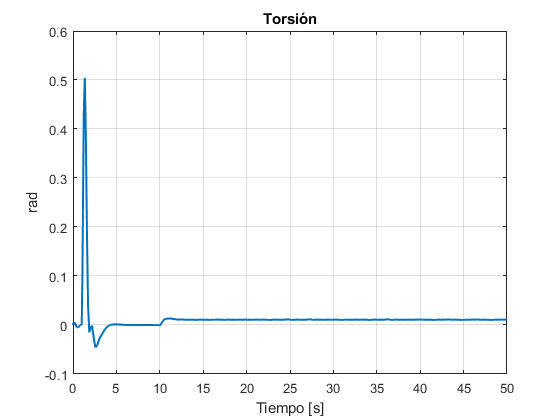

figure;
plot(tTorqueMonitor, Torque, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('rad');
title('Torsión');
grid on;

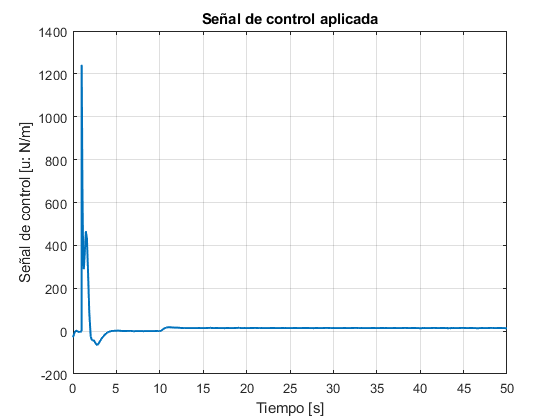

figure;
plot(tControlSignalMonitor, ControlSignal, 'LineWidth', 1.5);
xlabel('Tiempo [s]');
ylabel('Señal de control [u: N/m]');
title('Señal de control aplicada');
grid on;